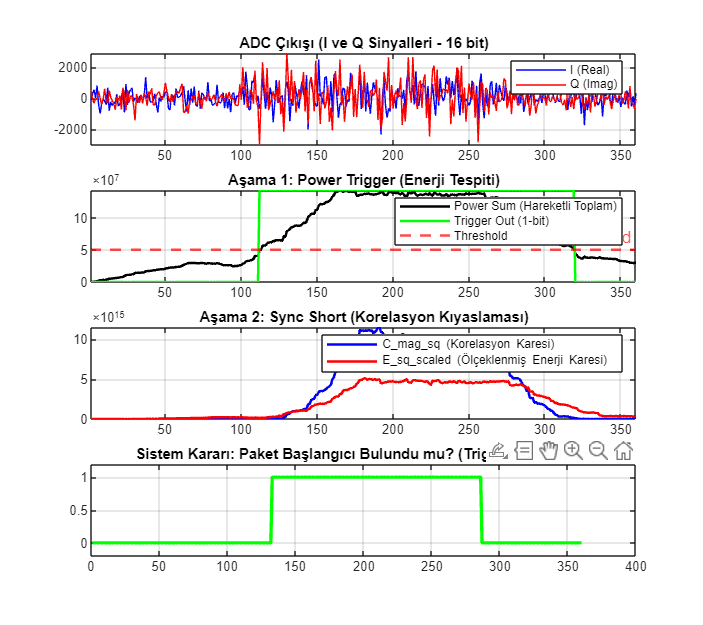

% =========================================================================
% 802.11n OFDM Sync Short & Power Trigger Testbench (Kalibre Edilmiş Sürüm)
% =========================================================================
clear; clc; close all;

%% 1. Test Verisi (Uyarıcı/Stimulus) Üretimi
% Wi-Fi 802.11n Short Preamble (L-STF) periyodu 16 örnekten oluşur.
D = 16;             % Gecikme miktarı (Periyot)
L = 64;             % Hareketli ortalama pencere boyutu
num_periods = 10;   % Preamble içinde 10 adet periyot bulunur (16x10 = 160 örnek)

% Rastgele bir periyodik sinyal (Preamble simülasyonu) oluşturalım
base_seq = complex(randn(D,1), randn(D,1)); 
preamble = repmat(base_seq, num_periods, 1);

% Paketin Öncesi ve Sonrası için Gürültü (Kanal Boşken)
noise_len = 100;
noise_var = 0.5; % Gürültü gücü

% Tam Sinyali Birleştirme: [Sessizlik/Gürültü -> Preamble Paketi -> Sessizlik]
tx_signal = [
    sqrt(noise_var/2) * complex(randn(noise_len,1), randn(noise_len,1));
    preamble + sqrt(noise_var/2) * complex(randn(length(preamble),1), randn(length(preamble),1));
    sqrt(noise_var/2) * complex(randn(noise_len,1), randn(noise_len,1))
];

% Donanımdaki ADC'yi (Analog-to-Digital Converter) simüle edelim.
ADC_scale = 1000; % Sinyali büyütüp tam sayıya yuvarlamak için
I_in = int16(real(tx_signal) * ADC_scale);
Q_in = int16(imag(tx_signal) * ADC_scale);

N = length(I_in);

%% 2. Donanım Modüllerini Çalıştırma
% --- Power Trigger Parametreleri ---
% Gürültü seviyesinin üstünde, preamble gücünün altında kalibre edilmiş eşik değeri
power_threshold = int64(50000000);
% --- Sync Short Parametreleri ---
% Donanımda enerjinin karesini büyütmek yerine, bitshift ile küçültüyoruz.
% E_shift_amount = 1 demek, enerjiyi 2'ye bölmek (sağa 1 bit kaydırmak) demektir.
E_shift_amount = 2; 
min_energy_threshold = int64(10000000); 

% 1. Aşama: Enerji Tespiti
[trigger_out, power_sum_out, inst_power_out] = power_trigger_hw_accurate(I_in, Q_in, L, power_threshold);

% 2. Aşama: Otokorelasyon ve Senkronizasyon Tespiti
[sync_detected, C_mag_sq, E_sq_scaled] = sync_short_hw_accurate(I_in, Q_in, D, L, E_shift_amount, min_energy_threshold);


%% 3. Hata Ayıklama (Debug) Grafikleri
figure('Name', 'OFDM Synchronization Testbench', 'NumberTitle', 'off', 'Position', [100, 100, 900, 800]);

% Alt Grafik 1: Giren Ham Sinyal
subplot(4,1,1);
plot(I_in, 'b'); hold on; plot(Q_in, 'r');
title('ADC Çıkışı (I ve Q Sinyalleri - 16 bit)');
legend('I (Real)', 'Q (Imag)');
grid on; axis tight;

% Alt Grafik 2: Power Trigger Çıktıları
subplot(4,1,2);
plot(power_sum_out, 'k', 'LineWidth', 1.5); hold on;
yline(double(power_threshold), 'r--', 'Threshold', 'LineWidth', 1.5);
plot(trigger_out * double(max(power_sum_out)), 'g', 'LineWidth', 1.5); 
title('Aşama 1: Power Trigger (Enerji Tespiti)');
legend('Power Sum (Hareketli Toplam)', 'Threshold', 'Trigger Out (1-bit)');
grid on; axis tight;

% Alt Grafik 3: Sync Short İç Sinyalleri (C_mag_sq vs E_sq_scaled)
subplot(4,1,3);
plot(C_mag_sq, 'b', 'LineWidth', 1.5); hold on;
plot(E_sq_scaled, 'r', 'LineWidth', 1.5);
title('Aşama 2: Sync Short (Korelasyon Kıyaslaması)');
legend('C\_mag\_sq (Korelasyon Karesi)', 'E\_sq\_scaled (Ölçeklenmiş Enerji Karesi)');
grid on; axis tight;

% Alt Grafik 4: Final Çıktıları (Karar)
subplot(4,1,4);
% Sadece trigger_out 1 iken sync_detected'ı dikkate alan "AND" kapısı mantığı
final_sync_decision = trigger_out & sync_detected;
plot(final_sync_decision, 'g', 'LineWidth', 2);
title('Sistem Kararı: Paket Başlangıcı Bulundu mu? (Trigger AND Sync)');
ylim([-0.2 1.2]);
grid on;


% =========================================================================
% FONKSİYONLAR 
% =========================================================================

function [trigger_out, power_sum_out, inst_power_out] = power_trigger_hw_accurate(I_in, Q_in, L, threshold)
    N = length(I_in);
    I_int = int64(I_in);
    Q_int = int64(Q_in);
    
    inst_power = I_int.^2 + Q_int.^2;
    inst_power_out = inst_power; 
    
    power_sum_full = filter(ones(1, L), 1, double(inst_power));
    
    power_sum_out = zeros(N, 1, 'int64');
    trigger_out = false(N, 1);
    
    for k = 1:N
        shift_amount = 0; % Verilog'a göre ayarlanmalı
        p_sum_kirpilmis = bitshift(int64(power_sum_full(k)), -shift_amount);
        power_sum_out(k) = p_sum_kirpilmis;
        trigger_out(k) = p_sum_kirpilmis > int64(threshold);
    end
end

function [sync_detected, C_mag_sq, E_sq_scaled] = sync_short_hw_accurate(I_in, Q_in, D, L, E_shift_amount, min_energy_threshold)
    N = length(I_in);
    
    I_d = [zeros(D, 1); I_in(1:end-D)];
    Q_d = [zeros(D, 1); Q_in(1:end-D)];
    
    conj_prod_real = int64(I_in) .* int64(I_d) + int64(Q_in) .* int64(Q_d);
    conj_prod_imag = int64(Q_in) .* int64(I_d) - int64(I_in) .* int64(Q_d);
    
    inst_energy = int64(I_d).^2 + int64(Q_d).^2;
    
    C_real_full = filter(ones(1, L), 1, double(conj_prod_real));
    C_imag_full = filter(ones(1, L), 1, double(conj_prod_imag));
    E_full      = filter(ones(1, L), 1, double(inst_energy));
    
    C_mag_sq = zeros(N, 1, 'int64');
    E_sq_scaled = zeros(N, 1, 'int64');
    sync_detected = false(N, 1);
    
    for k = 1:N
        shift_amount = 0; % Verilog'a göre ayarlanmalı
        
        c_r = bitshift(int64(C_real_full(k)), -shift_amount);
        c_i = bitshift(int64(C_imag_full(k)), -shift_amount);
        e_val = bitshift(int64(E_full(k)), -shift_amount);
        
        C_mag_sq(k) = c_r^2 + c_i^2;
        
        % Enerji karesini bitshift ile küçülterek donanım eşiğini oluşturuyoruz
        E_sq_scaled(k) = bitshift((e_val^2), -E_shift_amount); 
        
        cond1 = C_mag_sq(k) > E_sq_scaled(k);
        cond2 = e_val > int64(min_energy_threshold);
        
        sync_detected(k) = cond1 && cond2;
    end
end